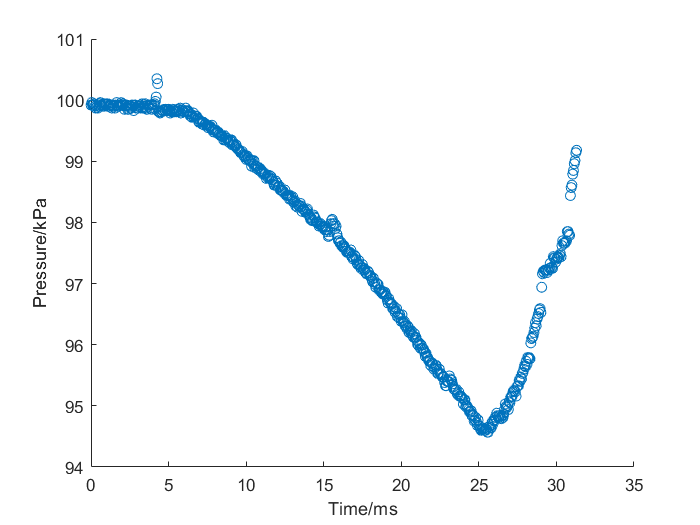

load test.txt;
s= size(test,1);
B = reshape(test,2,627);
t = 0:0.05:s*0.025-0.025;
x = B(2,:);

scatter(t,x);
xlabel('Time/ms');
ylabel('Pressure/kPa')

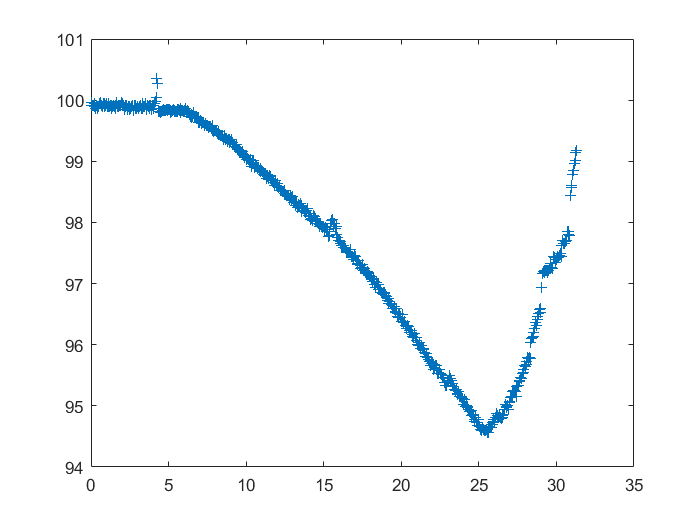

figure; plot(t,x,'+')


%displacement = integral of velocity 
%ypositive = find (y>=0);
Acceleration = B(1,:);
%sort(Acceleration,'accending');
timeinterval = 0.05;
speed = zeros(10000,1);
speed(1) = 0;
for i = [1:627]
    speed(i+1) = speed(i) + timeinterval * Acceleration(1,i);
end
speed

speed =          0
    0.4715
    0.9295
    1.3940
    1.8460
    2.3040
    2.7620
    3.2265
    3.6940
    4.1615


%[i,j,v] = find(speed > 0);
%maxheight = sum(v)*timeinterval;
